clear all;
close all;
%start time is Jun 12 2020 12:00:00
startTime = 20200612120000;
%end time is Jun 18 2020 17:00:00
endTime = 20200618170000;
%stn 067
stnID = 067;
gliderTable = readtable('metbuoy_26-04.csv');

cdipid = stnID; 
%convert startTime for cdip
    startTimestr = int2str(startTime);
    y_start = str2num(startTimestr(:,1:4));
    m_start = str2num(startTimestr(:,5:6));
    d_start = str2num(startTimestr(:,7:8));
    h_start = str2num(startTimestr(:,9:10));
    min_start = str2num(startTimestr(:,11:12));
    s_start = str2num(startTimestr(:,13:14));
    %convert endTime
    endTimestr = int2str(endTime);
    y_end = str2num(endTimestr(:,1:4));
    m_end = str2num(endTimestr(:,5:6));
    d_end = str2num(endTimestr(:,7:8));
    h_end = str2num(endTimestr(:,9:10));
    min_end = str2num(endTimestr(:,11:12));
    s_end = str2num(endTimestr(:,13:14));

tlims = [datenum(y_start,m_start,d_start,h_start,min_start,s_start) datenum(y_end, m_end,d_end,h_end,min_end,s_end)]; 

% spectral data etc. ------------------------------------------------------
clear cdip;
tres = 1;

varnm = 'Time';
[cdip.time] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Hs';
[cdip.hs] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'Tp';
[cdip.tp] = dload_cdipvar(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'EnergyDensity';
[cdip.sf, cdip.f] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



varnm = 'MeanDirection';
[cdip.md] = dload_cdipspec(cdipid,varnm,tlims, tres);

---> Not using CDIP realtime



%get waveglider time and wind vectors for appropriate times
[wgt,wgWind,wgMeanDir,~] = gliderTime(gliderTable, startTime, endTime);

%remove waveglider times that have no corresonding values in energy times
t_wind_new = NaN(length(cdip.time),1);
wind_wave_indices = NaN(length(cdip.time),1);
diff = 1000;
index = 1;
    for i = 1:length(cdip.time)
      for j = 1:length(wgt)
        if abs(cdip.time(i)-wgt(j)) < diff
            diff = abs(cdip.time(i)-wgt(j));
            index = j;
        end
      end
      t_wind_new(i) = wgt(index);
      wind_wave_indices(i) = index;
      index = 1;
      diff = 1000;
    end    
%new wind speeds
wgWind = wgWind(wind_wave_indices);
%new mean direction
wgMeanDir = wgMeanDir(wind_wave_indices);
%new wind times
wgt = wgt(wind_wave_indices);

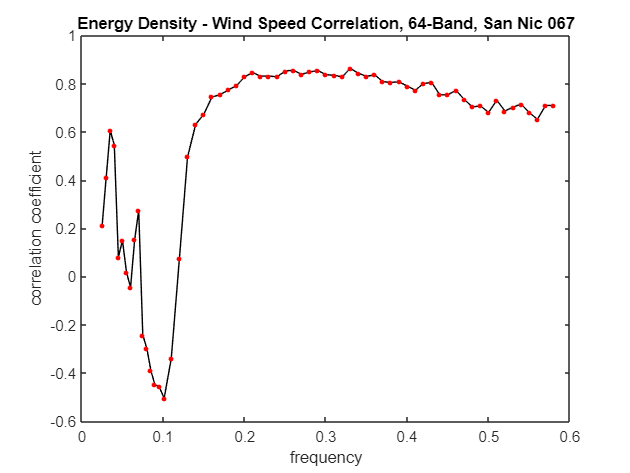

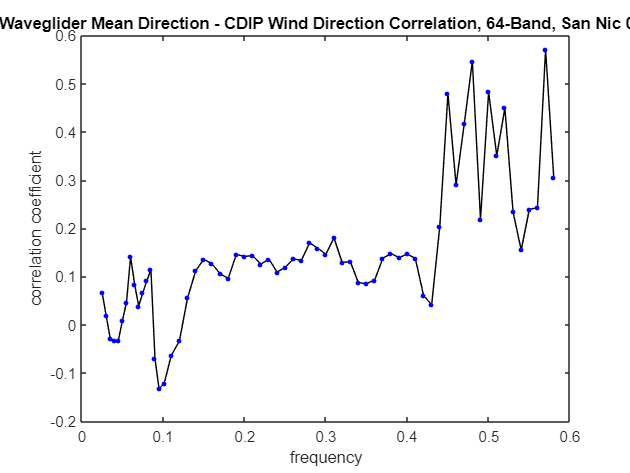

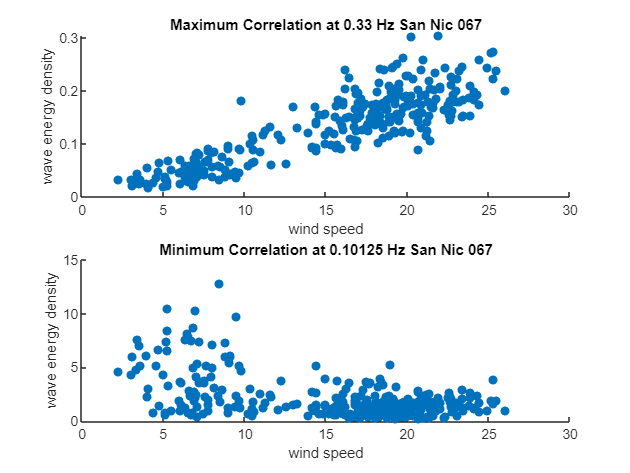

corr =     0.2093    0.4094    0.6062    0.5445    0.0788    0.1502    0.0173   -0.0446    0.1526    0.2739   -0.2426   -0.2983   -0.3907   -0.4497   -0.4560   -0.5046   -0.3406    0.0738    0.4958    0.6310    0.6727    0.7443    0.7534    0.7735    0.7905    0.8274    0.8452    0.8308    0.8312    0.8279    0.8517    0.8556    0.8378    0.8479    0.8541    0.8363    0.8347    0.8273    0.8633    0.8424    0.8299    0.8361    0.8077    0.8048    0.8069    0.7897    0.7726    0.7999    0.8046    0.7529


dircorr =     0.0670    0.0189   -0.0285   -0.0324   -0.0322    0.0086    0.0469    0.1410    0.0835    0.0387    0.0662    0.0911    0.1145   -0.0705   -0.1328   -0.1216   -0.0639   -0.0337    0.0555    0.1118    0.1358    0.1263    0.1058    0.0961    0.1458    0.1416    0.1434    0.1255    0.1361    0.1092    0.1190    0.1363    0.1335    0.1698    0.1587    0.1461    0.1801    0.1291    0.1307    0.0870    0.0853    0.0927    0.1379    0.1475    0.1393    0.1466    0.1370    0.0609    0.0414    0.2038


[corr, dircorr] = windWaveCorr64(' San Nic 067', wgWind, wgMeanDir, cdip)

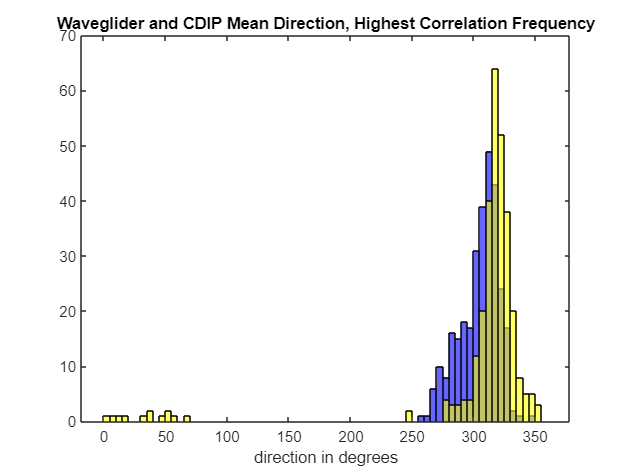

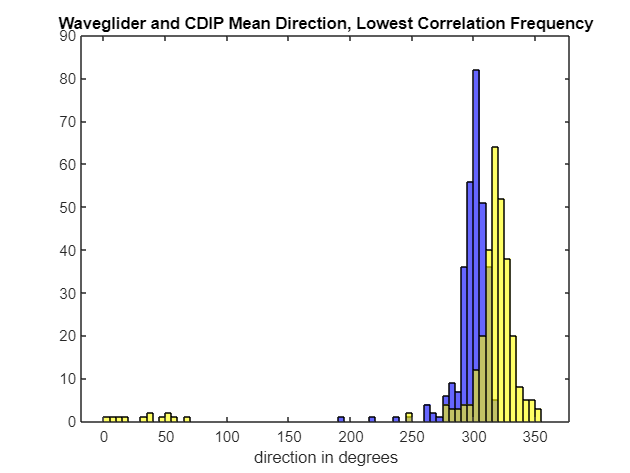

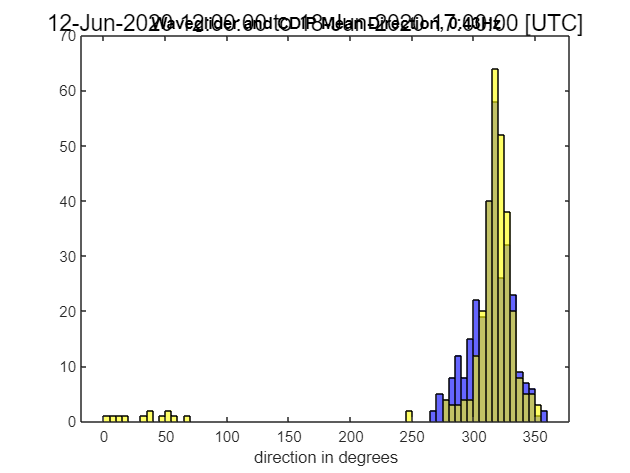

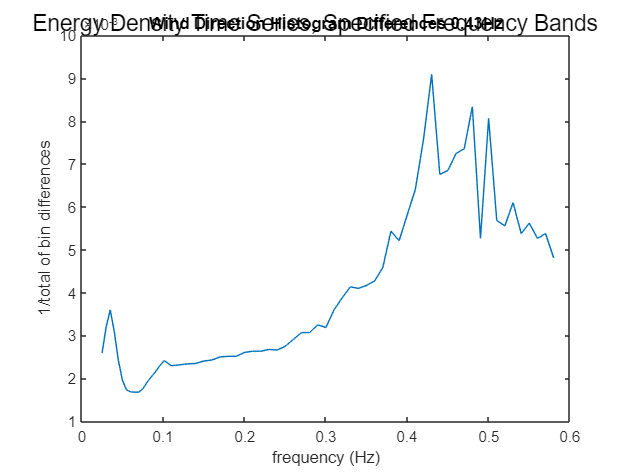

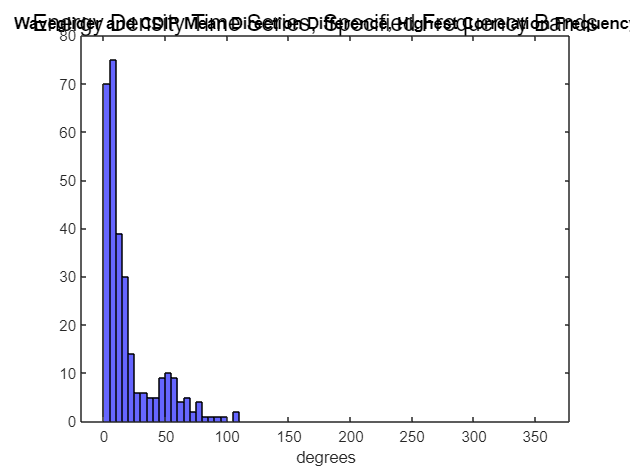

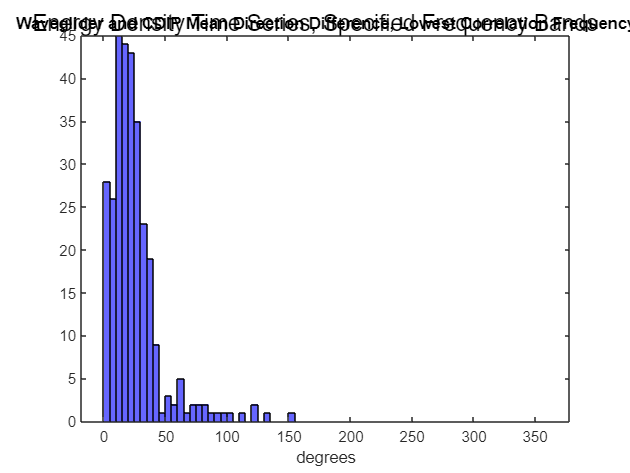

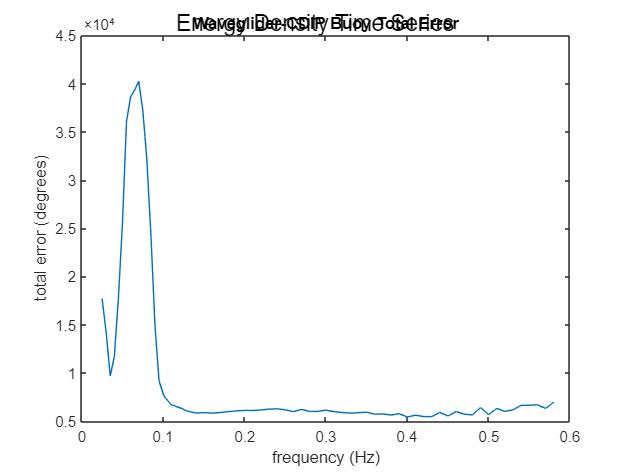

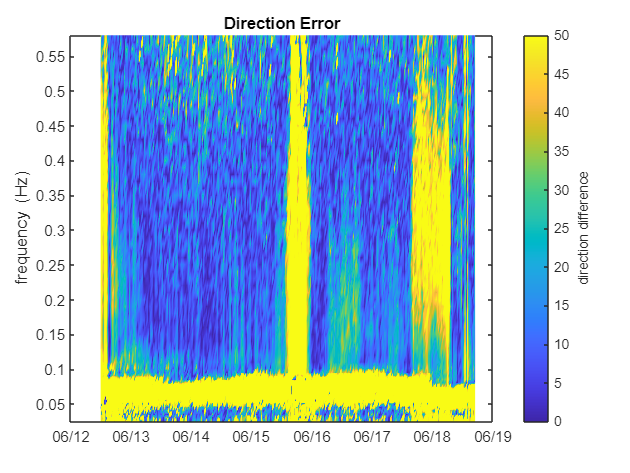

hist =     0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1013    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400
    0.0026    0.0032    0.0036    0.0031    0.0024    0.0020    0.0017    0.0017    0.0017    0.0017    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0023    0.0023    0.0023    0.0023    0.0024    0.0024    0.0025    0.0025    0.0025    0.0026    0.0026    0.0026    0.0027    0.0027    0.0027    0.0029    0.0031    0.0031    0.0032    0.0032    0.0036    0.0039    0.0041    0.0041    0.0042    0.0043    0.0046    0.0054    0.0052    0.0058    0.0064    0.0076    0.0091  

%direction histograms
hist = dir_histogram(cdip, wgMeanDir, corr)

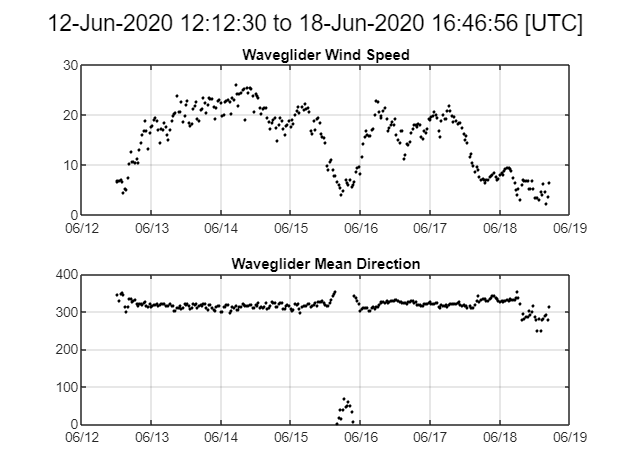

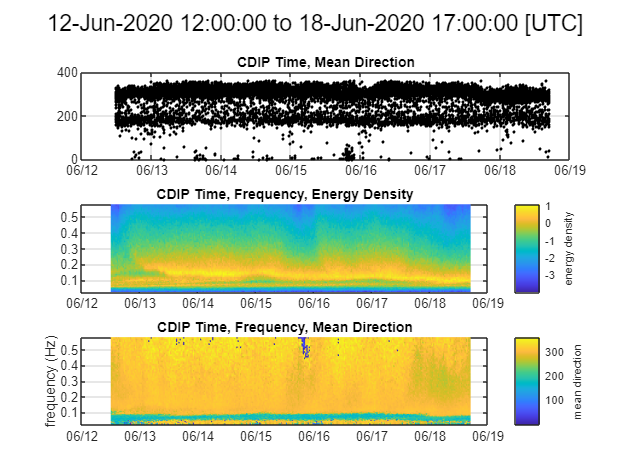

%pcolor plot
pcolor_plot(wgt, wgWind, wgMeanDir, cdip)

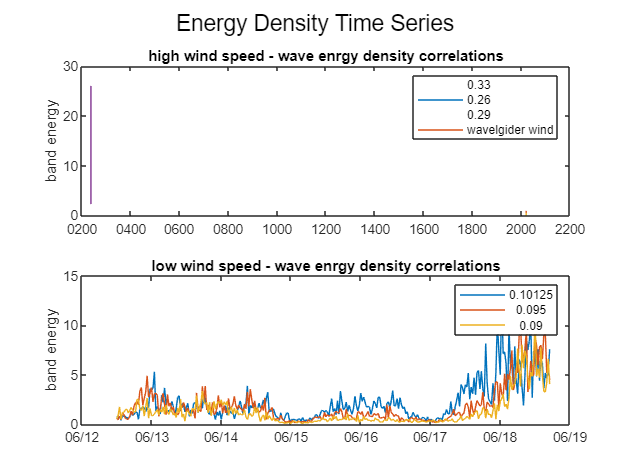

%energy density time series for selected frequency bands
freqplot(cdip, corr, wgt, wgWind)